# **Siavash Barqi   9523016**

#### a)

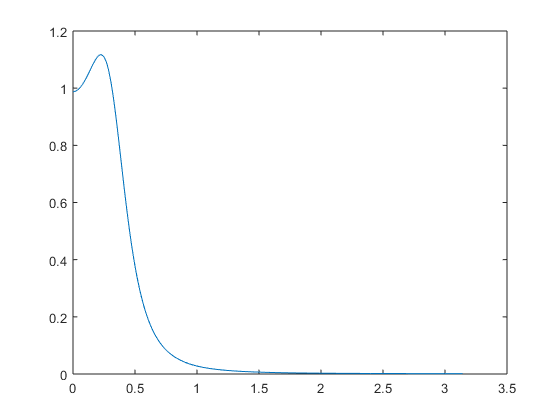

clc; clear; close all;
R = .8;
f0 = 500;
fs = 10000;
omega0 = 2*pi*f0/fs;
G = (1-R)*(1 - 2*R*cos(2*omega0) + R^2)^.5;
w = linspace(0,pi,500);
for i = 1:length(w)
    H2(i) = (G^2)/((1 - 2*R*cos(w(i) - omega0) + R^2)*(1 - 2*R*cos(w(i) + omega0) + R^2));
end
figure(1)
plot(w,H2)

#### b)

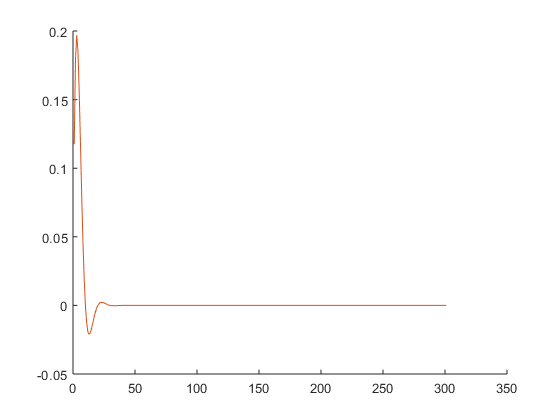

clc; clear; close all;
R = .8;
f0 = 500;
fs = 10000;
omega0 = 2*pi*f0/fs;
G = (1-R)*(1 - 2*R*cos(2*omega0) + R^2)^.5;
w = linspace(0,pi,500);
for i = 1:length(w)
    H2(i) = (G^2)/((1 - 2*R*cos(w(i) - omega0) + R^2)*(1 - 2*R*cos(w(i) + omega0) + R^2));
end
n = 0:300;
v = rand(1,length(n));
x = cos(omega0*n) + v;
a1 = -2*R*cos(omega0);
a2 = R^2;
x = zeros(1,length(n));
x(1) = 1;
y(1) = G*(x(1));
y(2) = -a1*y(1) + G*x(2);
for i=3:length(n)
    y(i) = -a1*y(i-1) - a2*y(i-2) + G*x(i);
end
n = n';
h = (R.^n).*sin(omega0.*n + omega0)*G/sin(omega0);
% h = h/G;
% y = y/G;
figure(2)
hold on
plot(y)
plot(h)

#### c)

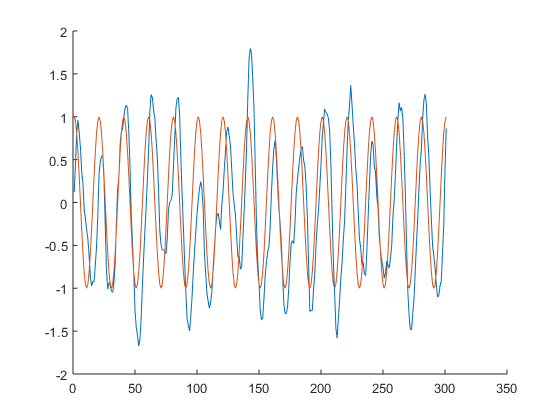

clc; clear; close all;
R = .8;
f0 = 500;
fs = 10000;
omega0 = 2*pi*f0/fs;
G = (1-R)*(1 - 2*R*cos(2*omega0) + R^2)^.5;
w = linspace(0,pi,500);
for i = 1:length(w)
    H2(i) = (G^2)/((1 - 2*R*cos(w(i) - omega0) + R^2)*(1 - 2*R*cos(w(i) + omega0) + R^2));
end
n = 0:300;
v = randn(1,length(n));
x = cos(omega0*n) + v;
s = cos(omega0*n);
a1 = -2*R*cos(omega0);
a2 = R^2;
w2 = G*(x(1));
w1 = -a1*w2 + G*x(2);
y(1) = w2;
y(2) = w1;
for i=3:length(n)
    y(i) = -a1*w1 - a2*w2 + G*x(i);
    w2 = w1;
    w1 = y(i);
end
% n = n';
figure(2)
% y = y/G;
hold on
plot(y)
plot(s)

#### d)

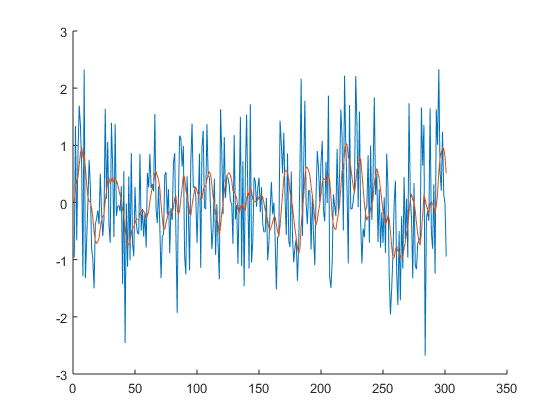

clc;close all; clear;
R = .8;
f0 = 500;
fs = 10000;
omega0 = 2*pi*f0/fs;
G = (1-R)*(1 - 2*R*cos(2*omega0) + R^2)^.5;
w = linspace(0,pi,500);
for i = 1:length(w)
    H2(i) = (G^2)/((1 - 2*R*cos(w(i) - omega0) + R^2)*(1 - 2*R*cos(w(i) + omega0) + R^2));
end
n = 0:300;
v = randn(1,length(n));
x = cos(omega0*n) + v;
s = cos(omega0*n);
a1 = -2*R*cos(omega0);
a2 = R^2;
w2 = G*(x(1));
w1 = -a1*w2 + G*x(2);
y(1) = w2;
y(2) = w1;
for i=3:length(n)
    y(i) = -a1*w1 - a2*w2 + G*v(i);
    w2 = w1;
    w1 = y(i);
end
% n = n';
figure(2)
% y = y/G;
hold on
plot(v)
plot(y)

#### e)

clc; clear; close all;
R = .99;
f0 = 500;
fs = 10000;
omega0 = 2*pi*f0/fs;
G = (1-R)*(1 - 2*R*cos(2*omega0) + R^2)^.5;
w = linspace(0,pi,500);
for i = 1:length(w)
    H2(i) = (G^2)/((1 - 2*R*cos(w(i) - omega0) + R^2)*(1 - 2*R*cos(w(i) + omega0) + R^2));
end
n = 0:3000;
v = randn(1,length(n));
x = cos(omega0*n) + v;
s = cos(omega0*n);
a1 = -2*R*cos(omega0);
a2 = R^2;
w2 = G*(v(1));
w1 = -a1*w2 + G*v(2);
y(1) = w2;
y(2) = w1;
for i=3:length(n)
    y(i) = -a1*w1 - a2*w2 + G*v(i);
    w2 = w1;
    w1 = y(i);
end

sigmayv = std(y)^2;
sigmav = std(v)^2;

NRR = sigmayv/sigmav

NRR = 0.0125


NRRtheory = (1+R^2)/((1+R)*(1+2*R*cos(omega0)+R^2))

NRRtheory = 0.2576